
 Unique Cluster # 1

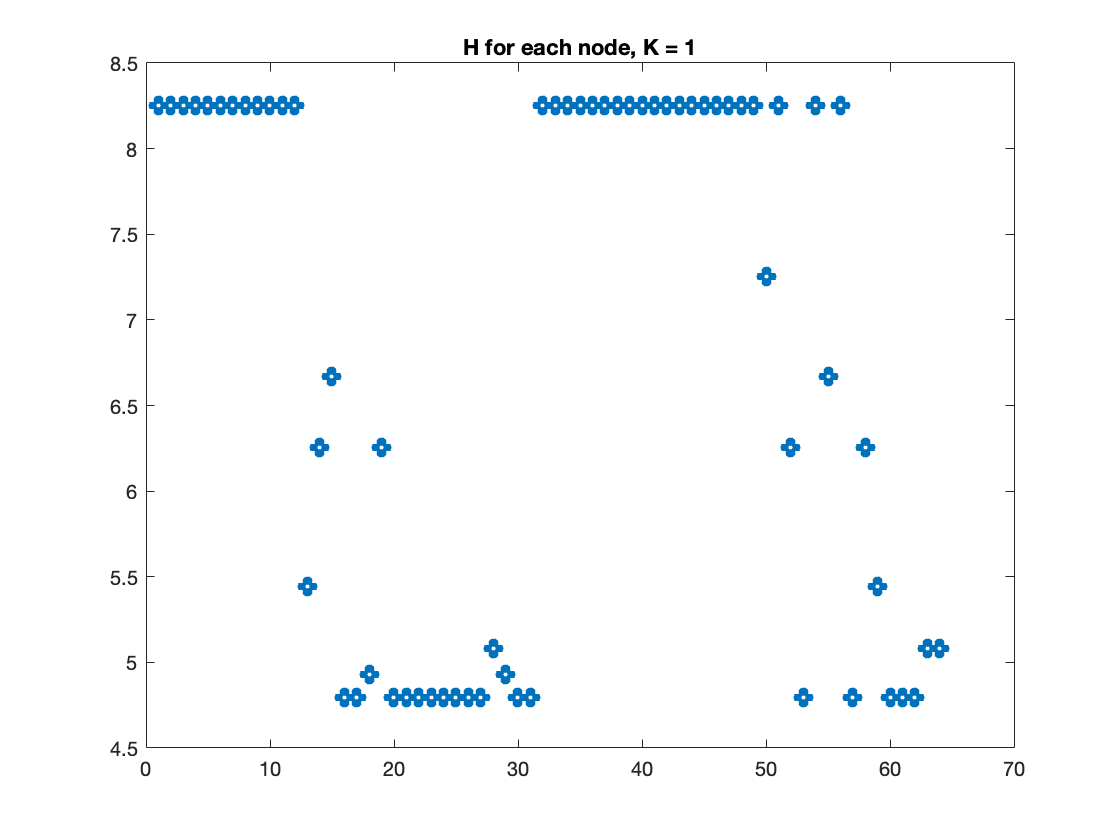


 Unique Cluster # 2

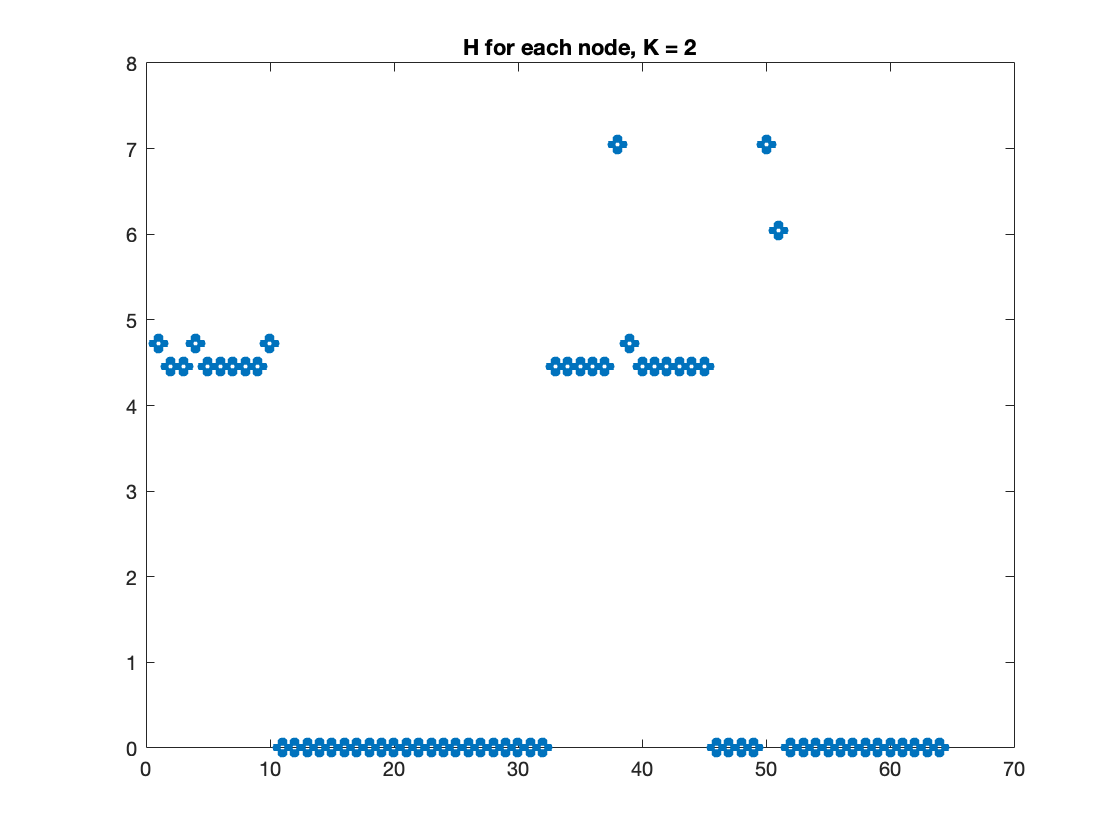


 Unique Cluster # 3

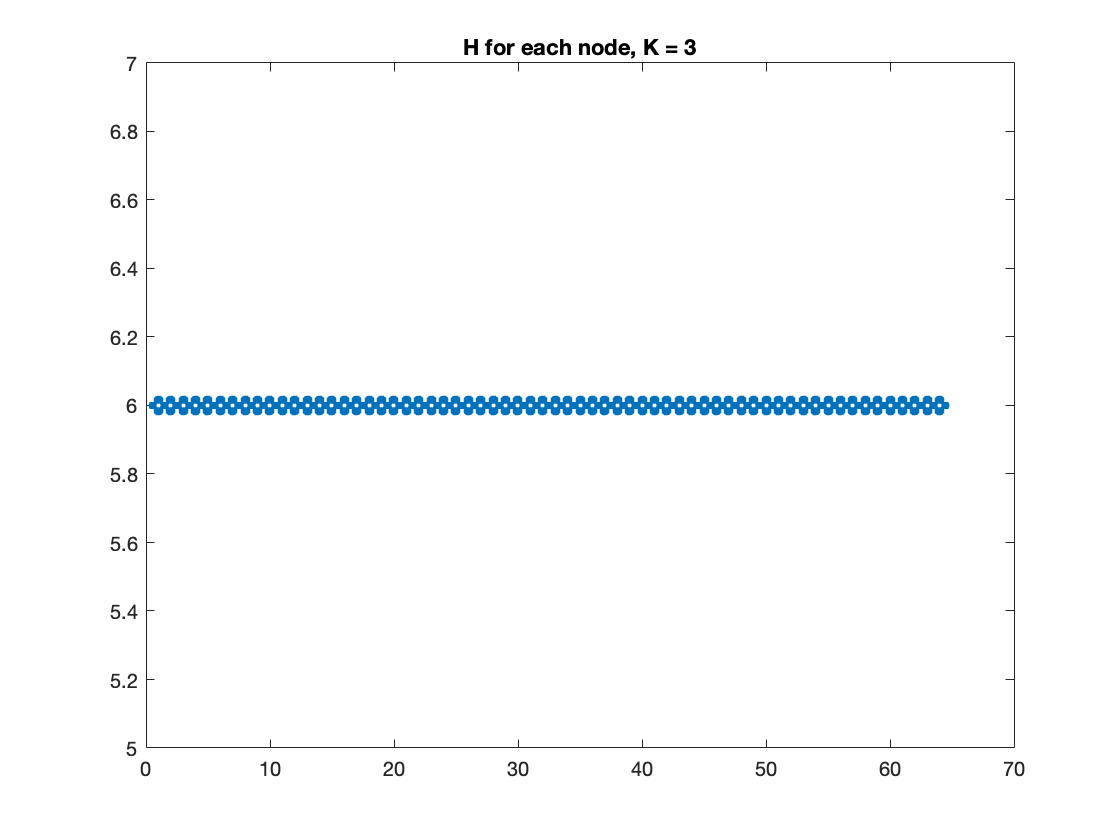


 Unique Cluster # 4

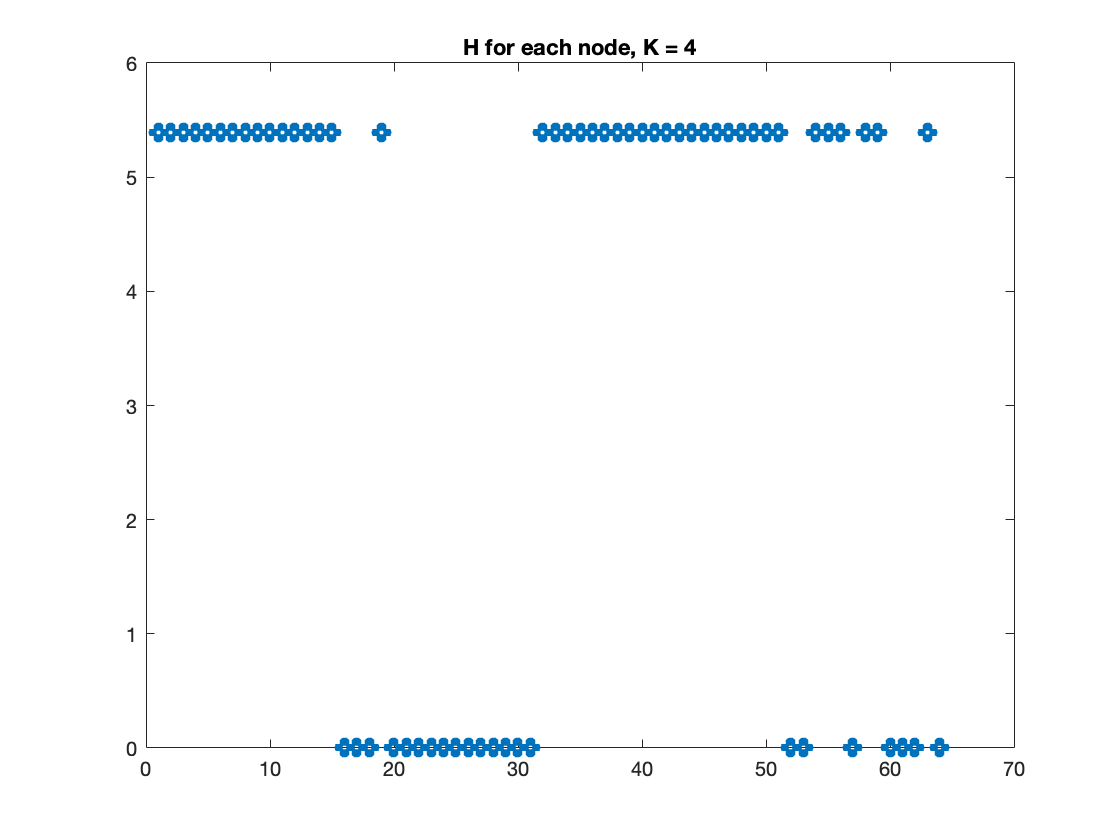


 Unique Cluster # 5

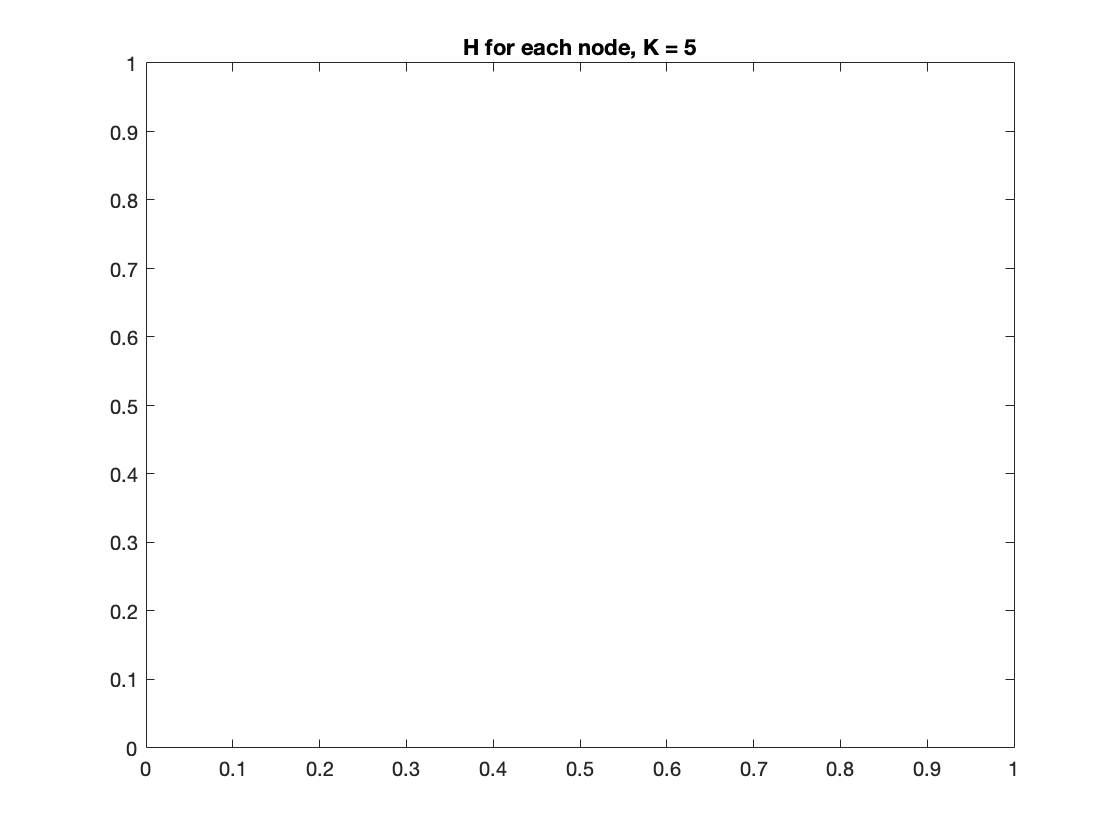


 Unique Cluster # 6

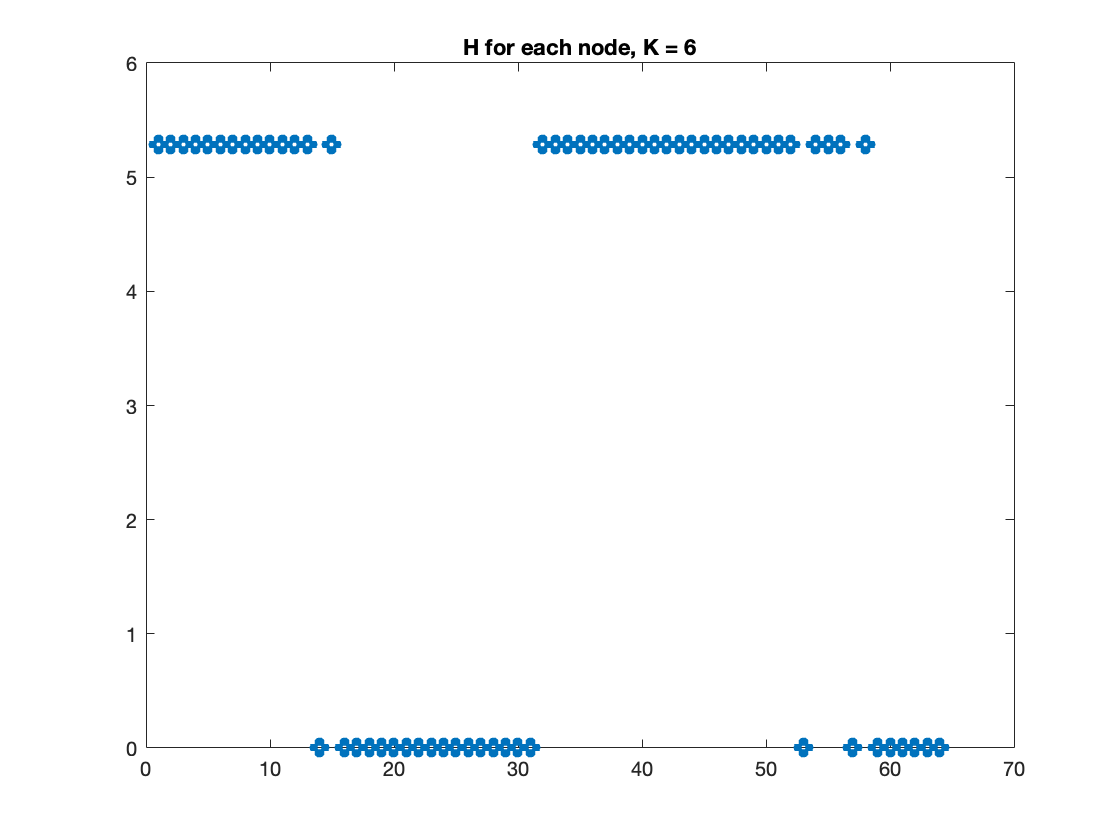


 Unique Cluster # 7

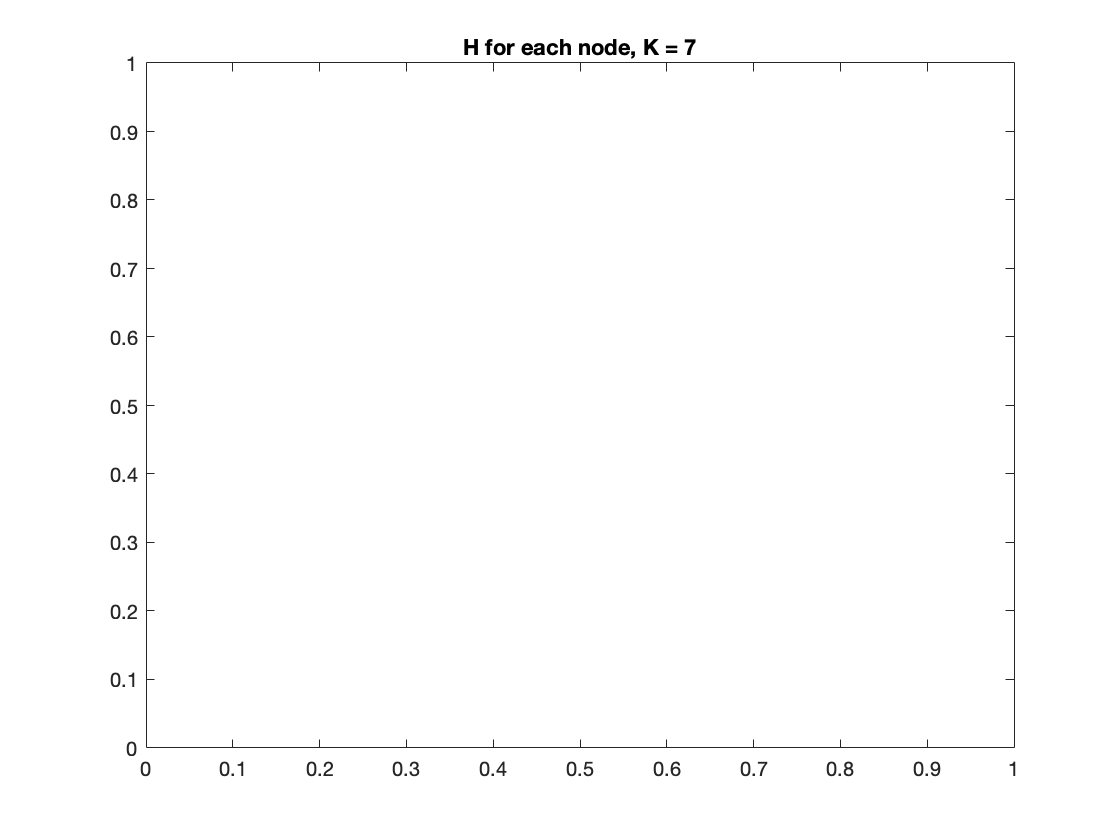


 Unique Cluster # 8

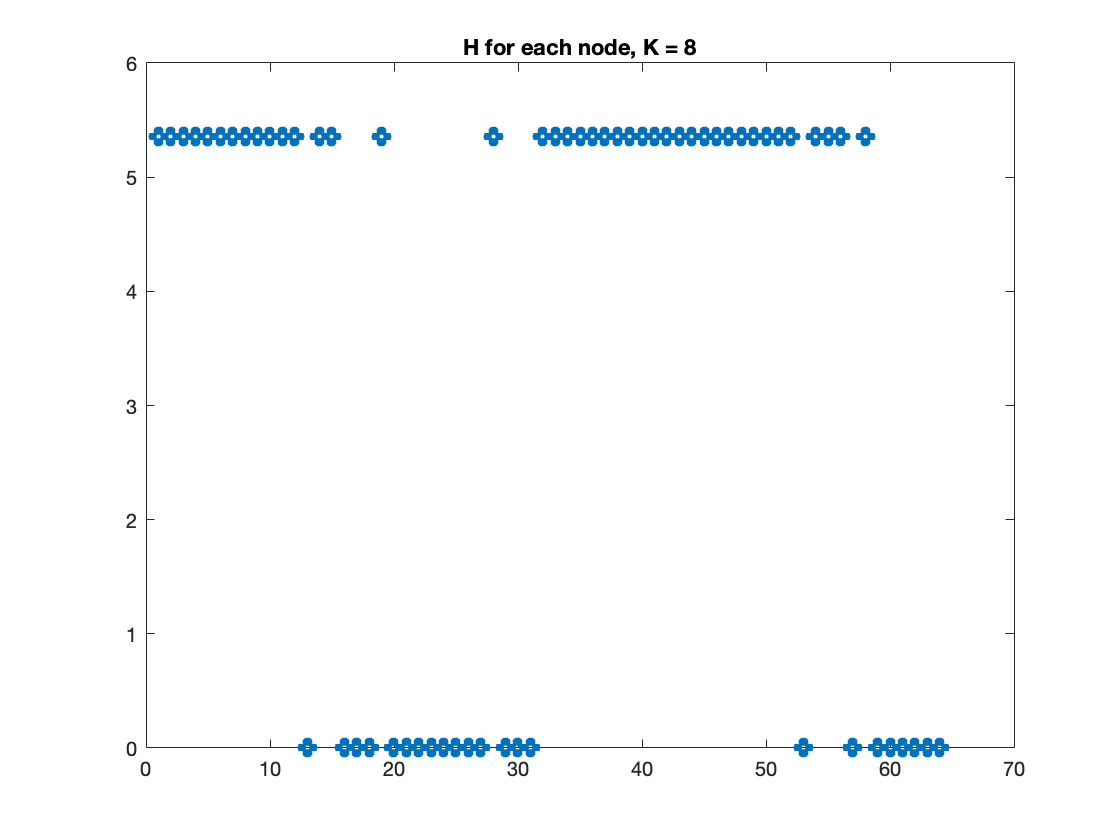


 Unique Cluster # 9

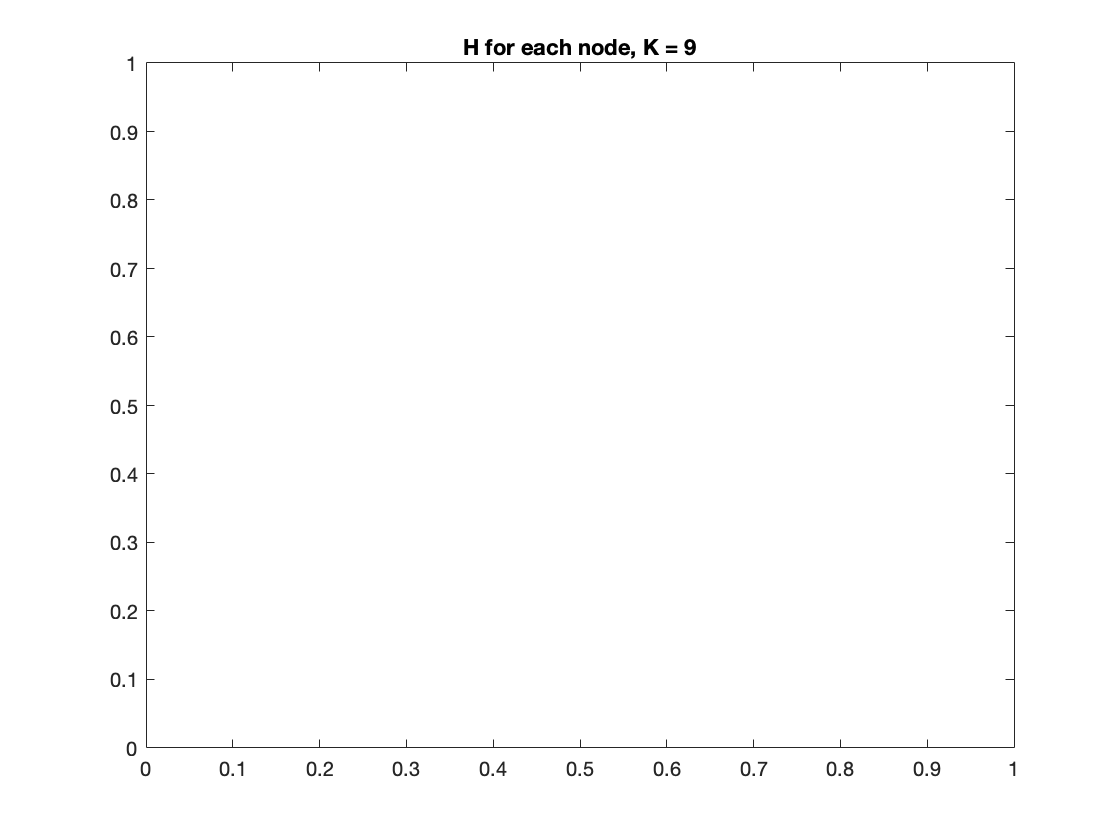


 Unique Cluster # 10

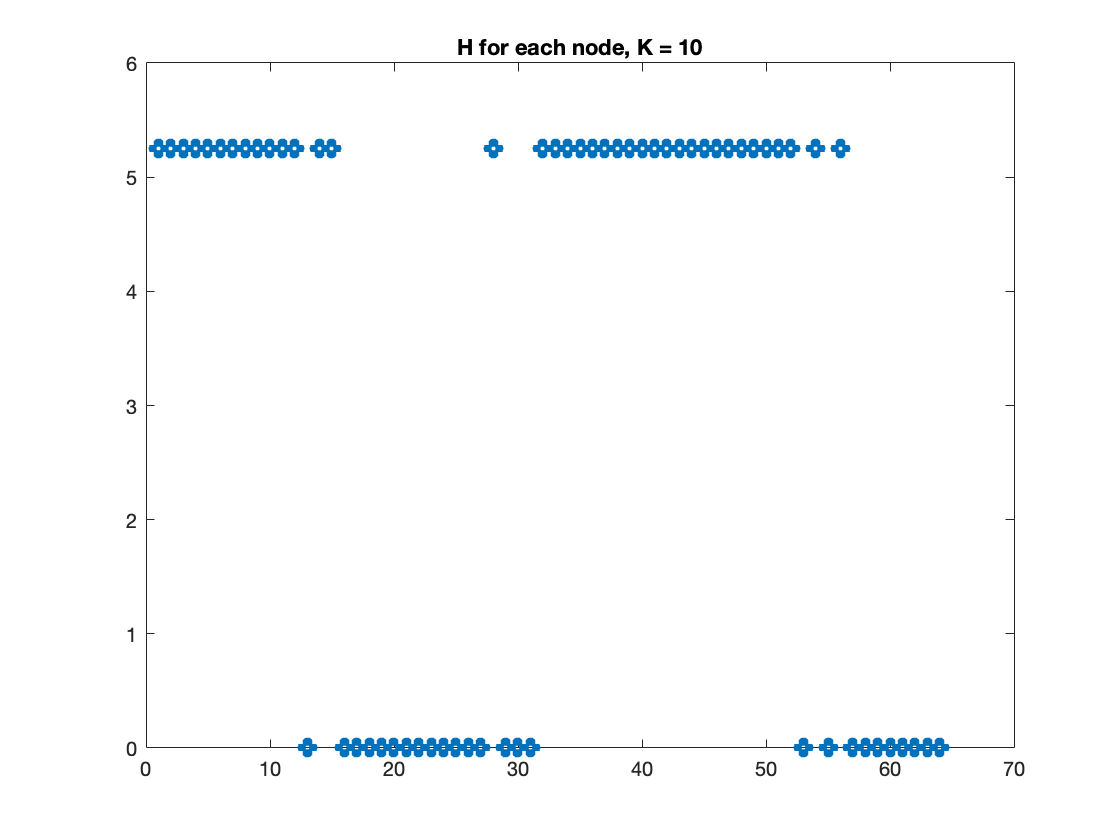


 Unique Cluster # 11

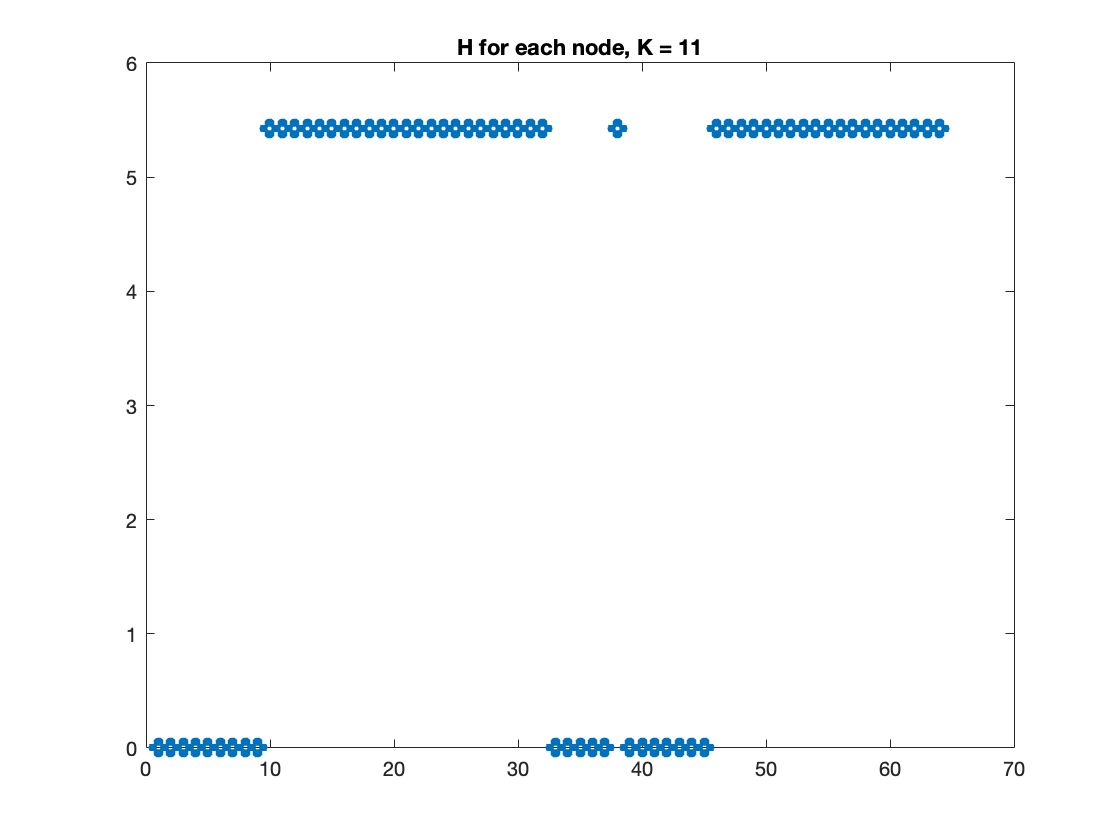


 Unique Cluster # 12

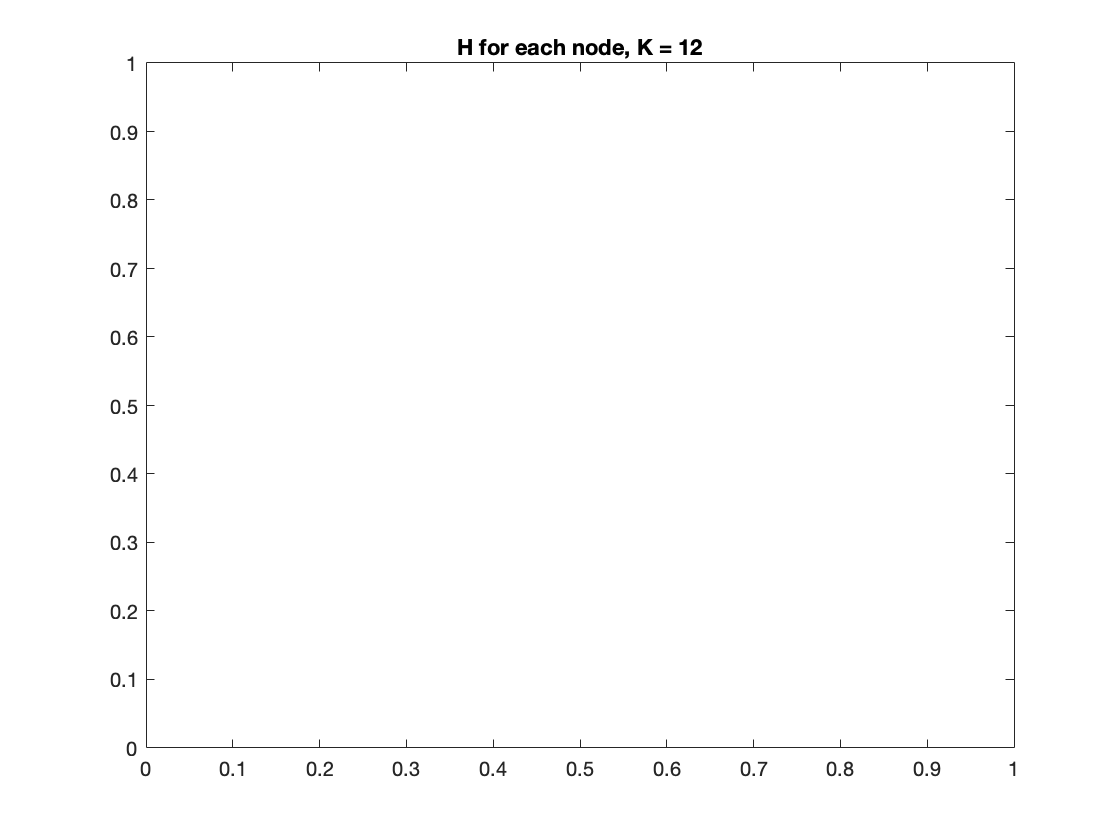


 Unique Cluster # 13

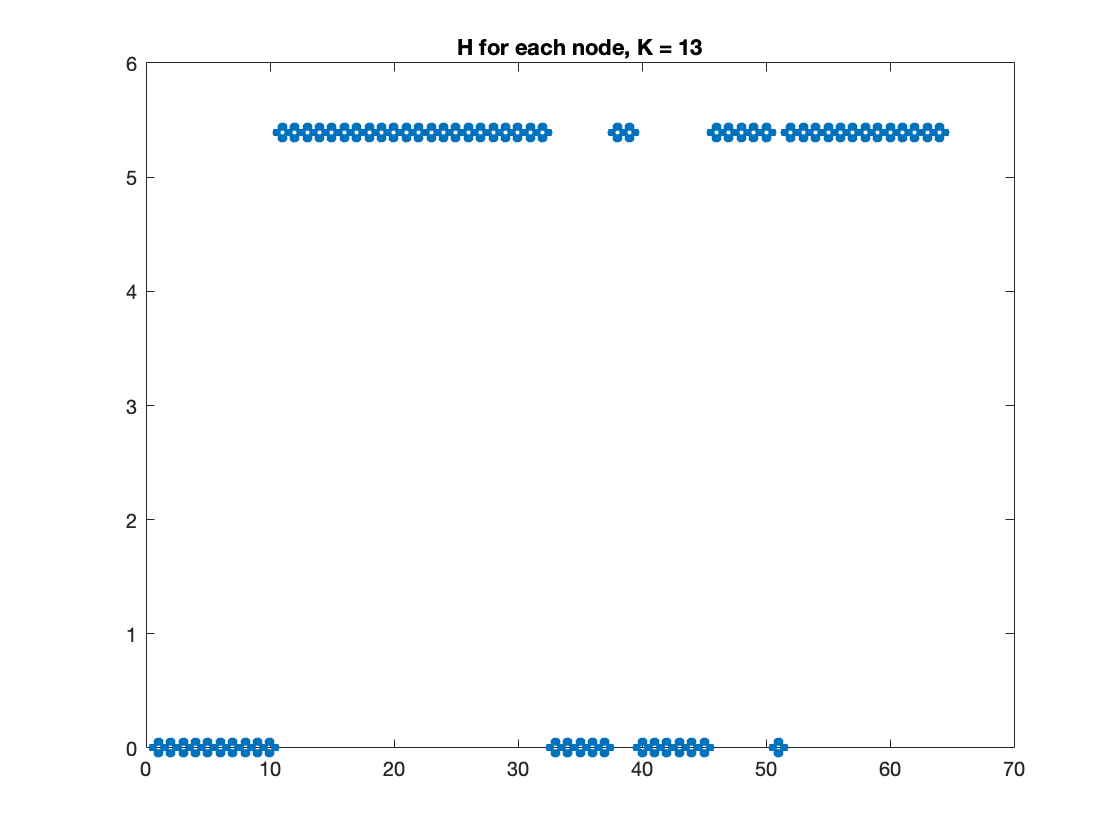


 Unique Cluster # 14

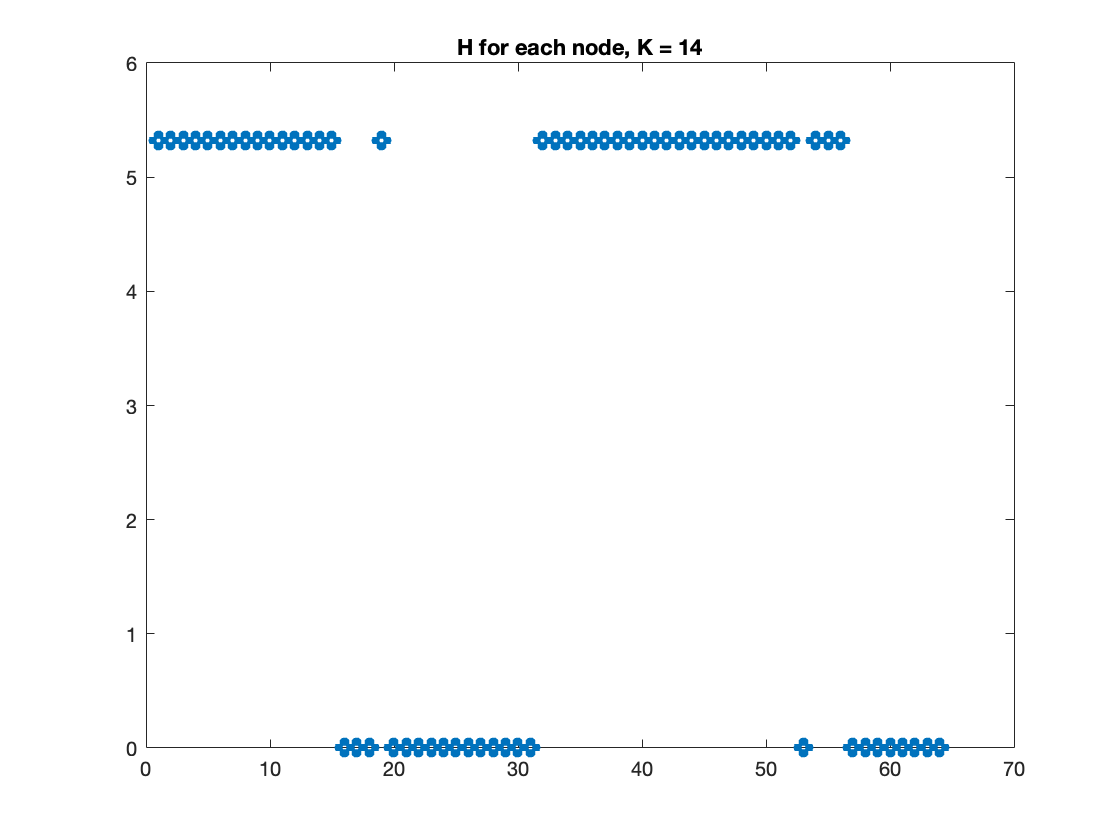


 Unique Cluster # 15

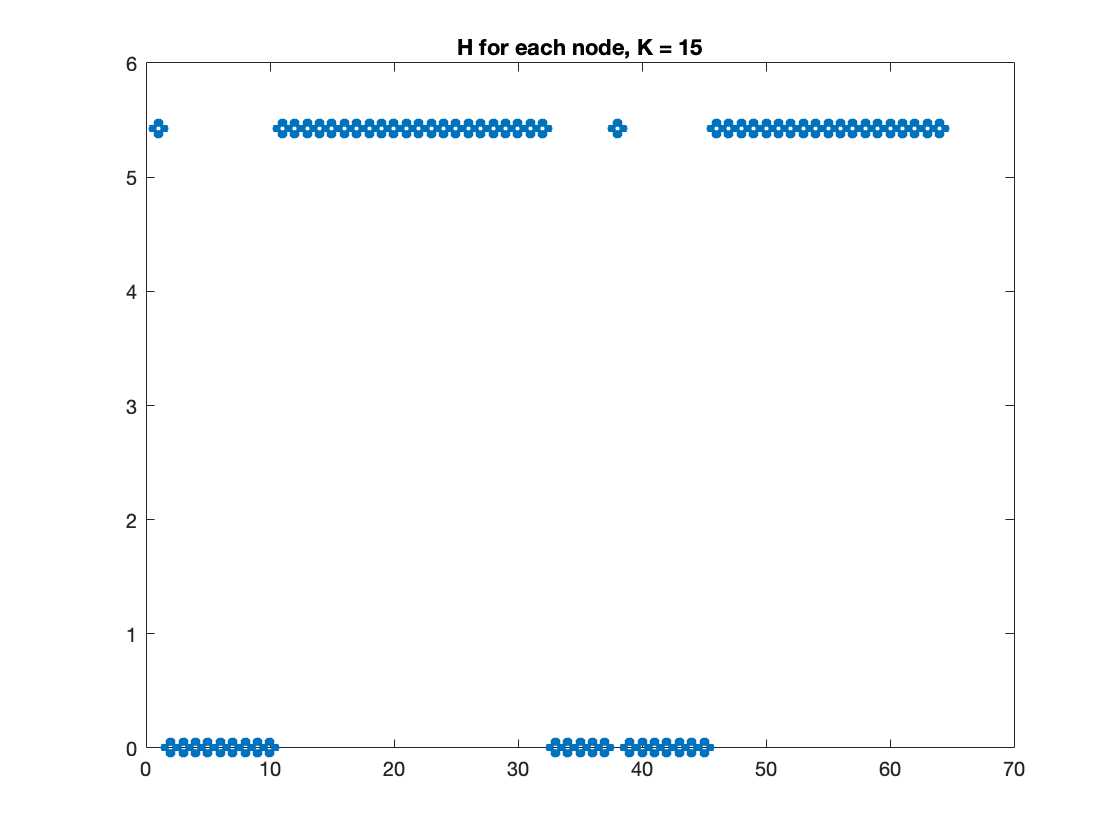


 Unique Cluster # 16

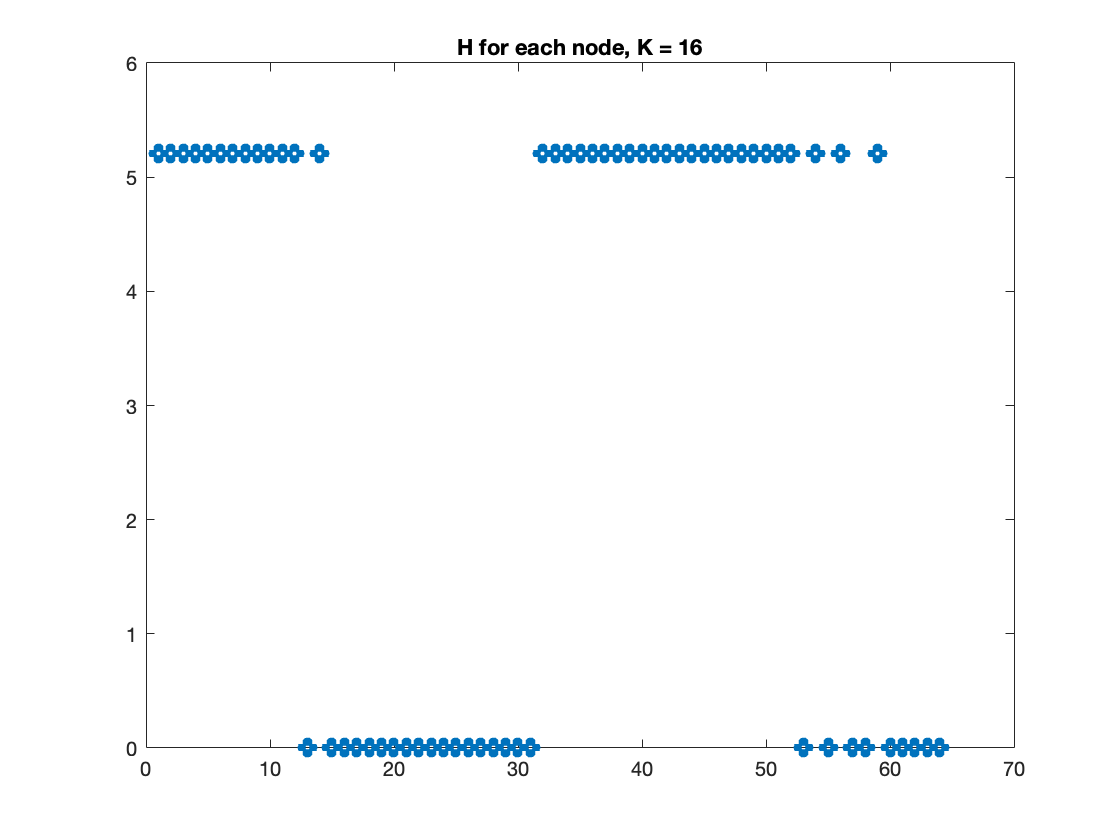


 Unique Cluster # 17

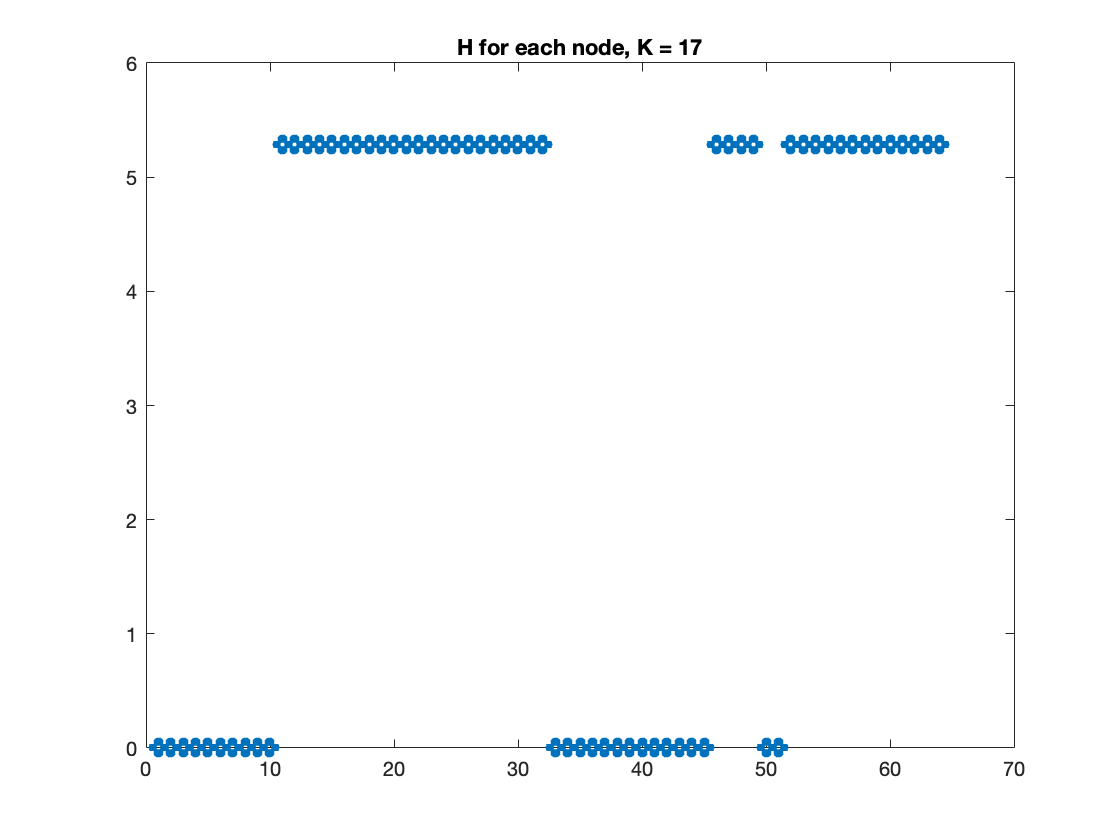


 Unique Cluster # 18

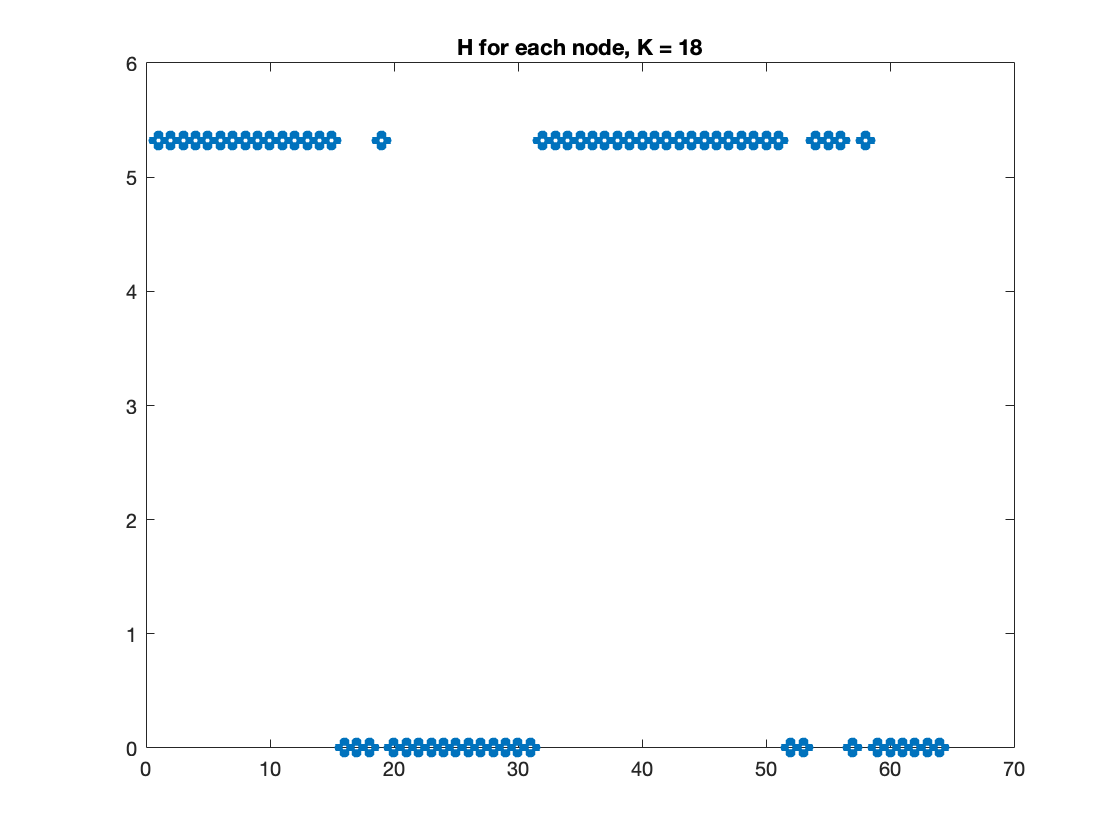


 Unique Cluster # 19

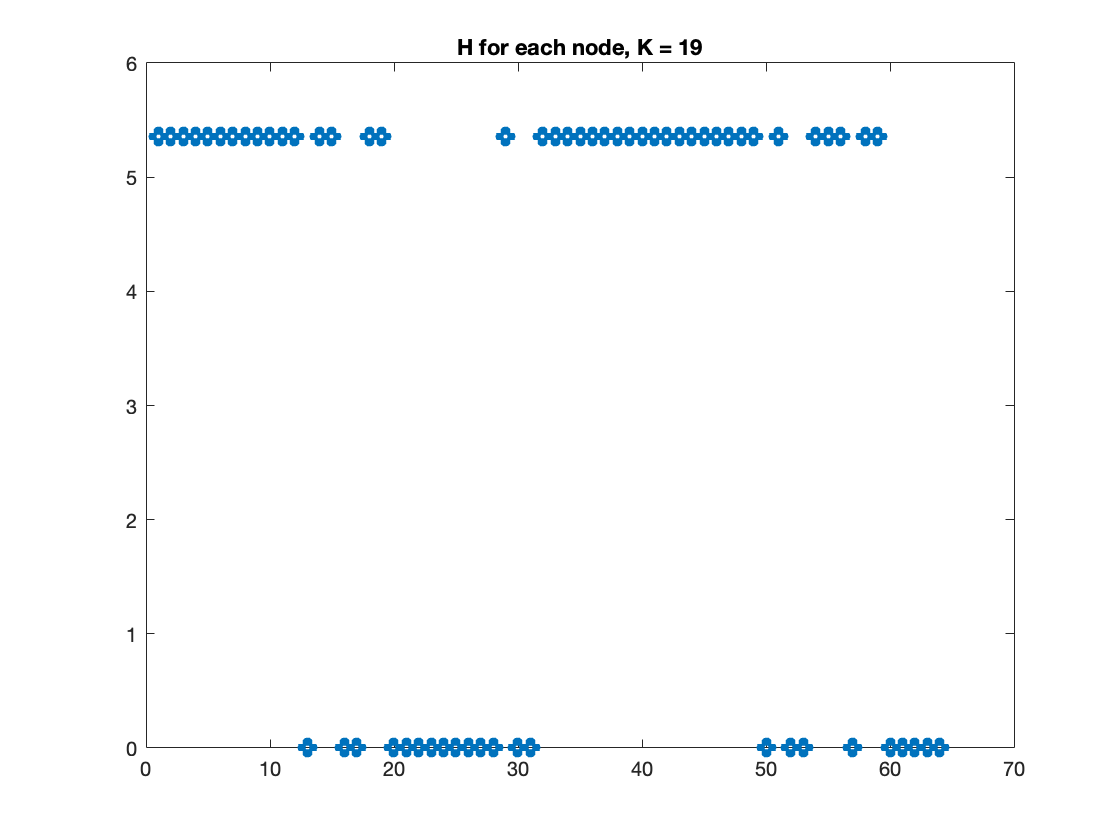


 Unique Cluster # 20

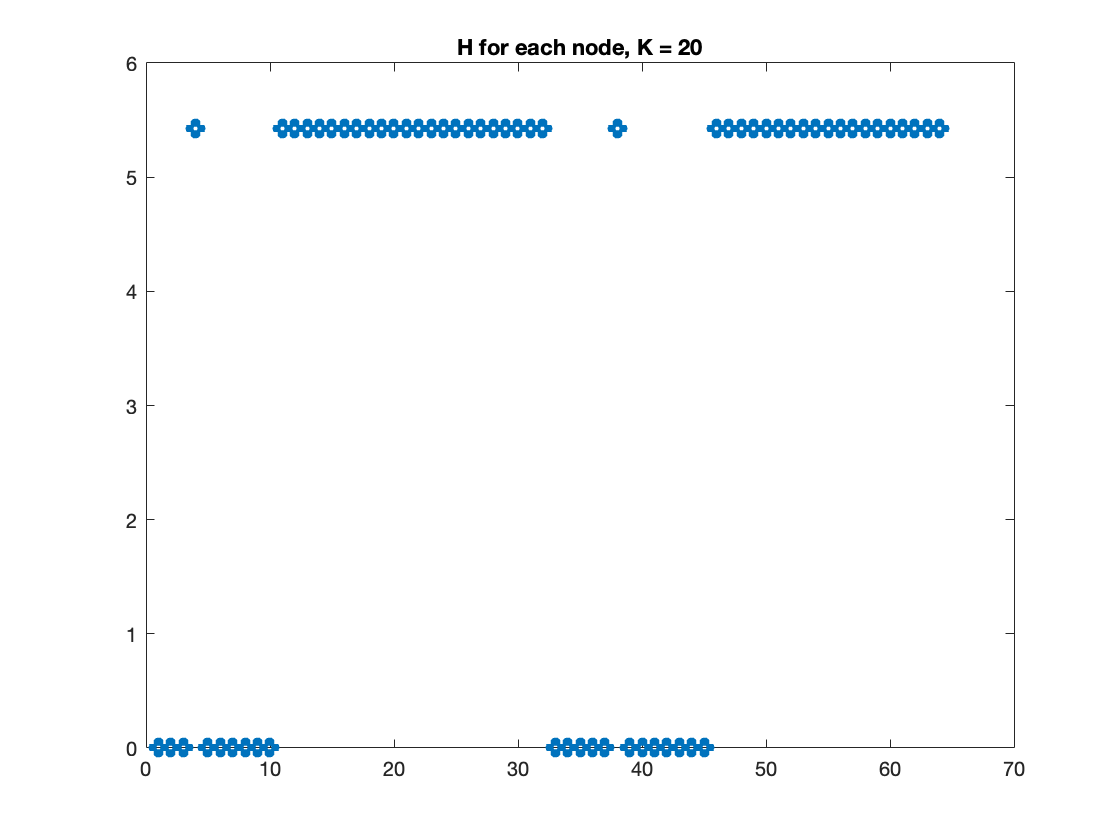


 Unique Cluster # 21

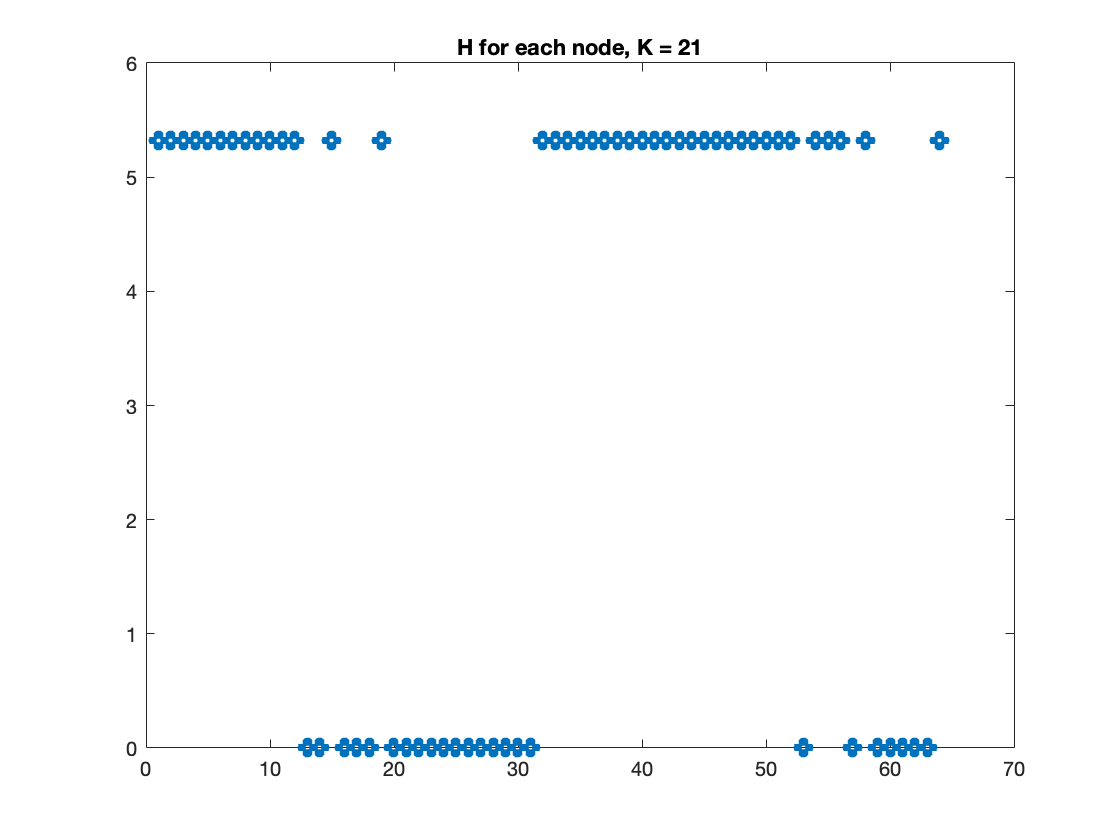


 Unique Cluster # 22

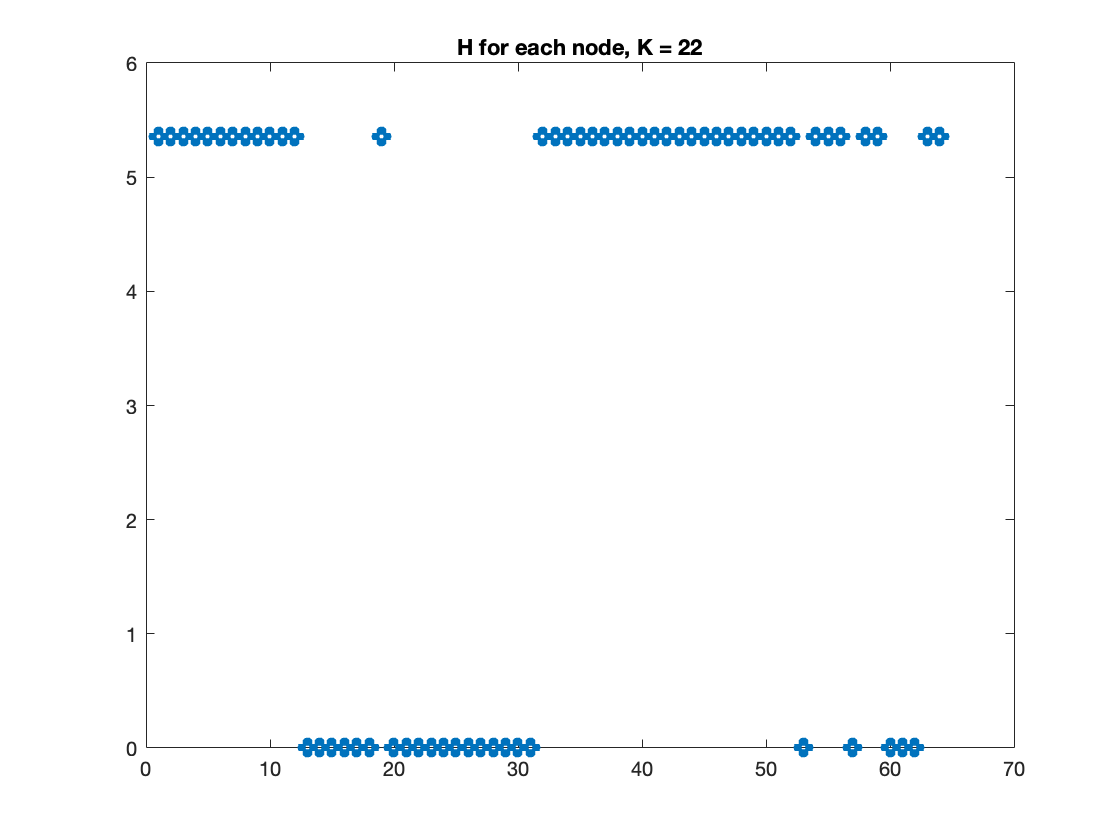


 Unique Cluster # 23

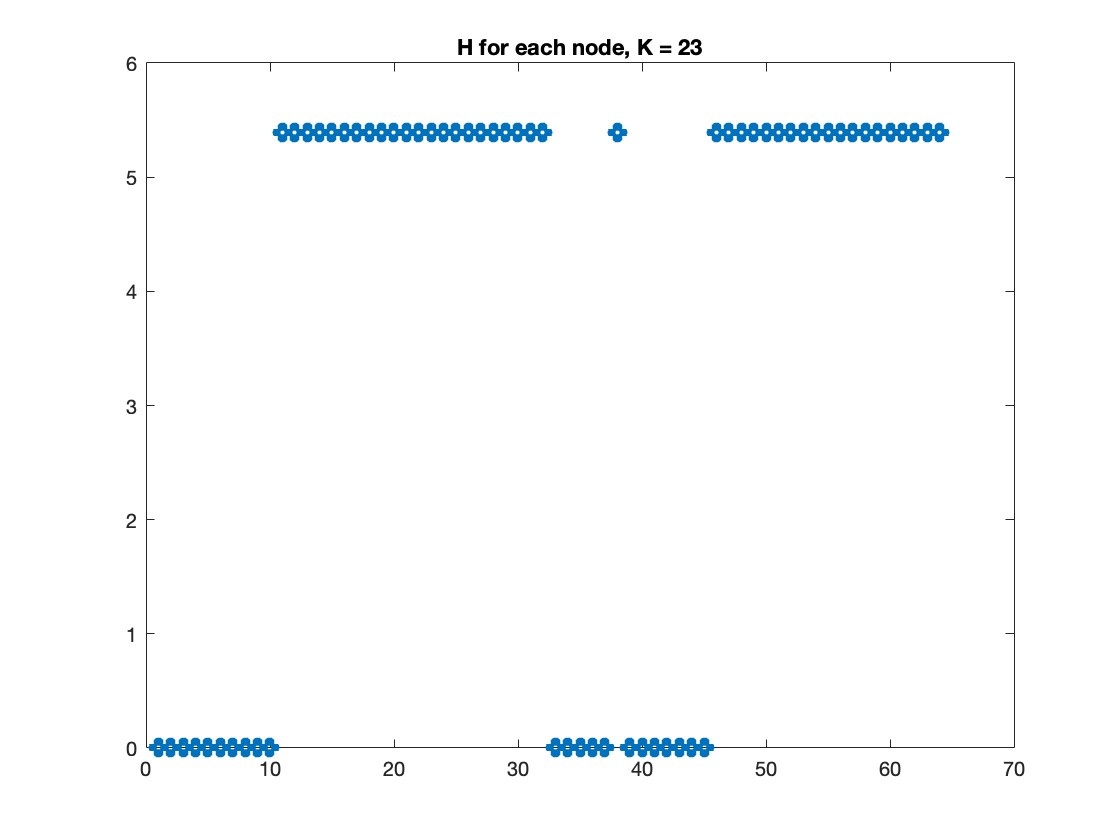

% K communities (common + private ) _> for each node, quantify its
% varibality/consistency across subjects based on community structure ->
% for each node across all subjects generate a length K vector 
% {g_{i}} , each entry will tell you how many times out of 20 subjects node
% i was assigned to community, k -> Normalize this vector to obtain
% probability distribution
% p_{i} = g_{i}/sum_{i}g_{i},
%compute entropy {H(i) = sum(i)p(i)log2p(i)
%generalized louvain algorithm
%use git code multicat: https://github.com/GenLouvain/GenLouvain/blob/master/HelperFunctions/multiaspect.m
%multilayer modularity (categorical coupling)
%undirected layers



load("intercluster_strength_data_A09threshold.mat")

un_len; %all unqiue clusters private and common
layer_nodes_per_cluster; %is 1xunique clusters cell, each cell, L rows by 64 columns
%if the node is in that cluster in that layer than binary marked as 1

%g -> each entry will tell you how many times out of 20 subjects node i was assigned to community
g = [];

%probability distribution
p = [];

%entropy
%lower entropy , high variability
%high entropy, not much variation
H = [];



for i=1:un_len
    
    fprintf("\n Unique Cluster # %d", i)
    
    cluster_i_nodes = sum(layer_nodes_per_cluster{i});
    g = [g, {cluster_i_nodes}];
    all_nodes_sum_per_cluster = sum(cluster_i_nodes);
%     
%     figure;
%     plot(cluster_i_nodes,'o','LineWidth',4);
%     hold on;
%     title(sprintf('G for each node, K = %d', i));
%     hold off;
    
    p_cluster_i = cluster_i_nodes/all_nodes_sum_per_cluster;
    p = [p, {p_cluster_i}];
    
%     figure;
%     plot(p_cluster_i,'o','LineWidth',4);
%     hold on;
%     title(sprintf('P for each node, K = %d', i));
%     hold off;
    
    all_prob_sum_per_cluster = sum(p_cluster_i);
    
    entropy_of_i_cluster = -1*all_prob_sum_per_cluster*log2(p_cluster_i);
    entropy_of_i_cluster(isinf(entropy_of_i_cluster)) = 0; %sets inf to zero
    H = [H, {entropy_of_i_cluster}];
    
    figure;
    plot(entropy_of_i_cluster,'o','LineWidth',4)
    hold on;
    title(sprintf('H for each node, K = %d', i));
    hold off;
    
    
end